# 3. Different SVM Models

This live script is intended as supplementary material for section 3 of the report. For this live script, we will create a small dataset on which to test our Support Vector Machine models, and compare our four methods on this small dataset. In order to run this script, you will need to have installed both the MOSEK optimisation package for MATLAB, as well as the YALMIP interface. For full details on formulations and meanings of variables and terms, please see Section 3 of the report.

### Dataset

For easy visualisation, we will consider $m=16$ data points, with only $n=2$ features. The first class of points (labelled as $+1$) will be lie within a square of size $2$ centred around the point $\left(2,2\right)$, whereas the second class of points (labelled as $-1$) will lie within a square of size $2$ centred at $\left(3,3\right)$. 

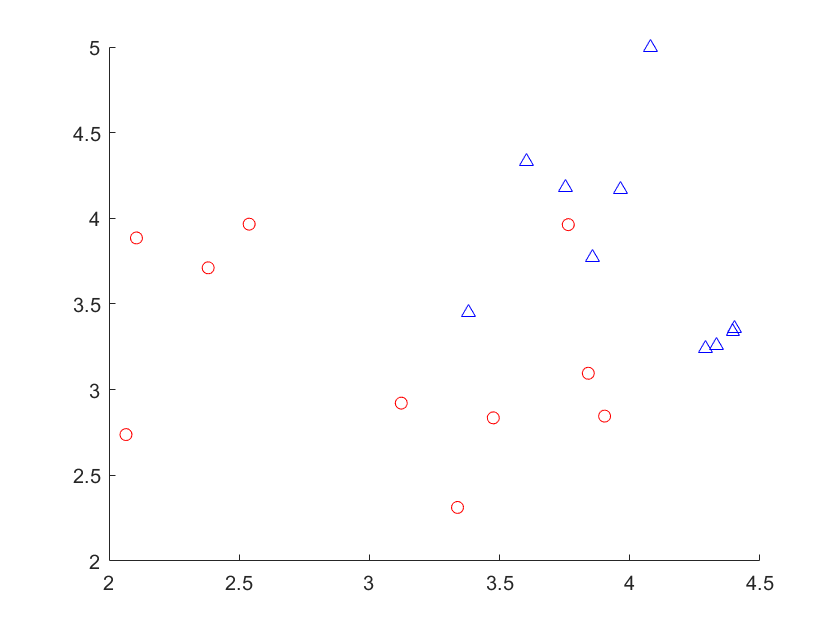

x = [2*rand(5,2) + 2;
     2*rand(5,2) + 3];
y = [ones(5,1);
    -ones(5,1)];

scatter(x(1:5,1),x(1:5,2),'ro')
hold on
scatter(x(6:end,1),x(6:end,2),'b^')

As we can see, this data is **not **linearly separable, and so our soft-margin models are required.

### Model 1: Standard SVM

The standard SVM is formulated as a quadratic program in dual form:

## 
$${\mathrm{min}}_u \;\;\frac{1}{2}{u^T \mathit{YXX}}^T Y^T u-e^T u\;\;\mathrm{subject}\;\mathrm{to}\;\;e^T Y^T u=0,0\le u\le \nu \;e$$


Below we create a function that takes as input, the data points $x$, their classification $y$ and the regularization parameter $\lambda \;$, then solves the above optimisation problem, and returns the weights $w$, the bias $\gamma \;$, and values of the soft margin errors $\xi \;$, as well as an array of indices that indicate the support vectors. 